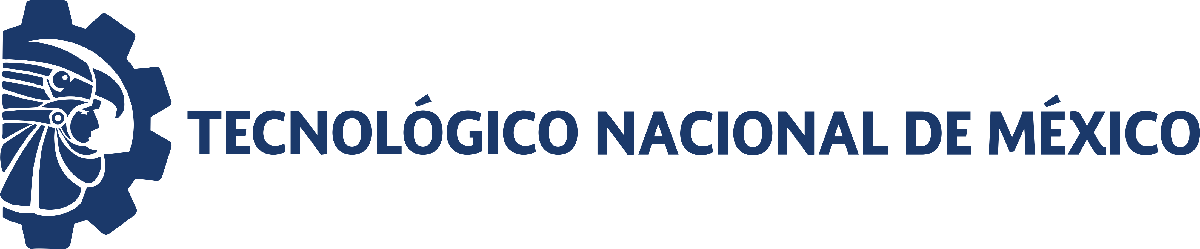                                 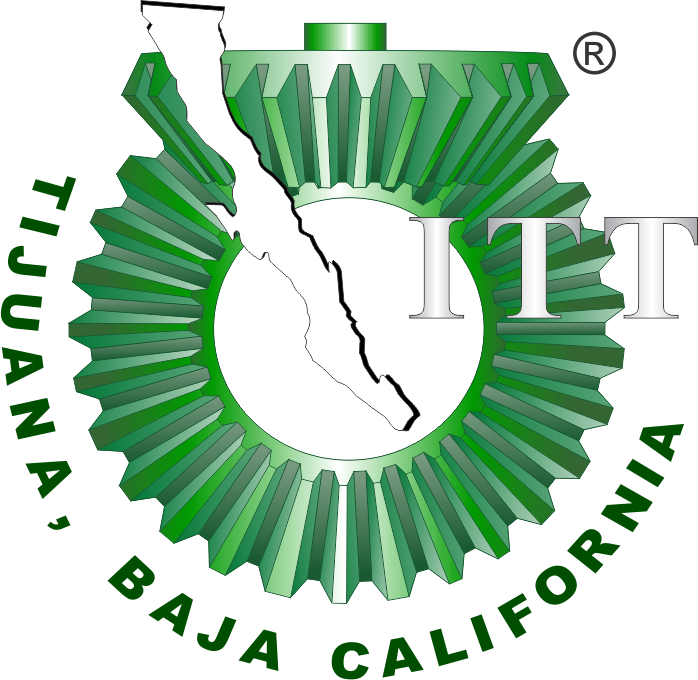

# Práctica 2: Sistema Cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

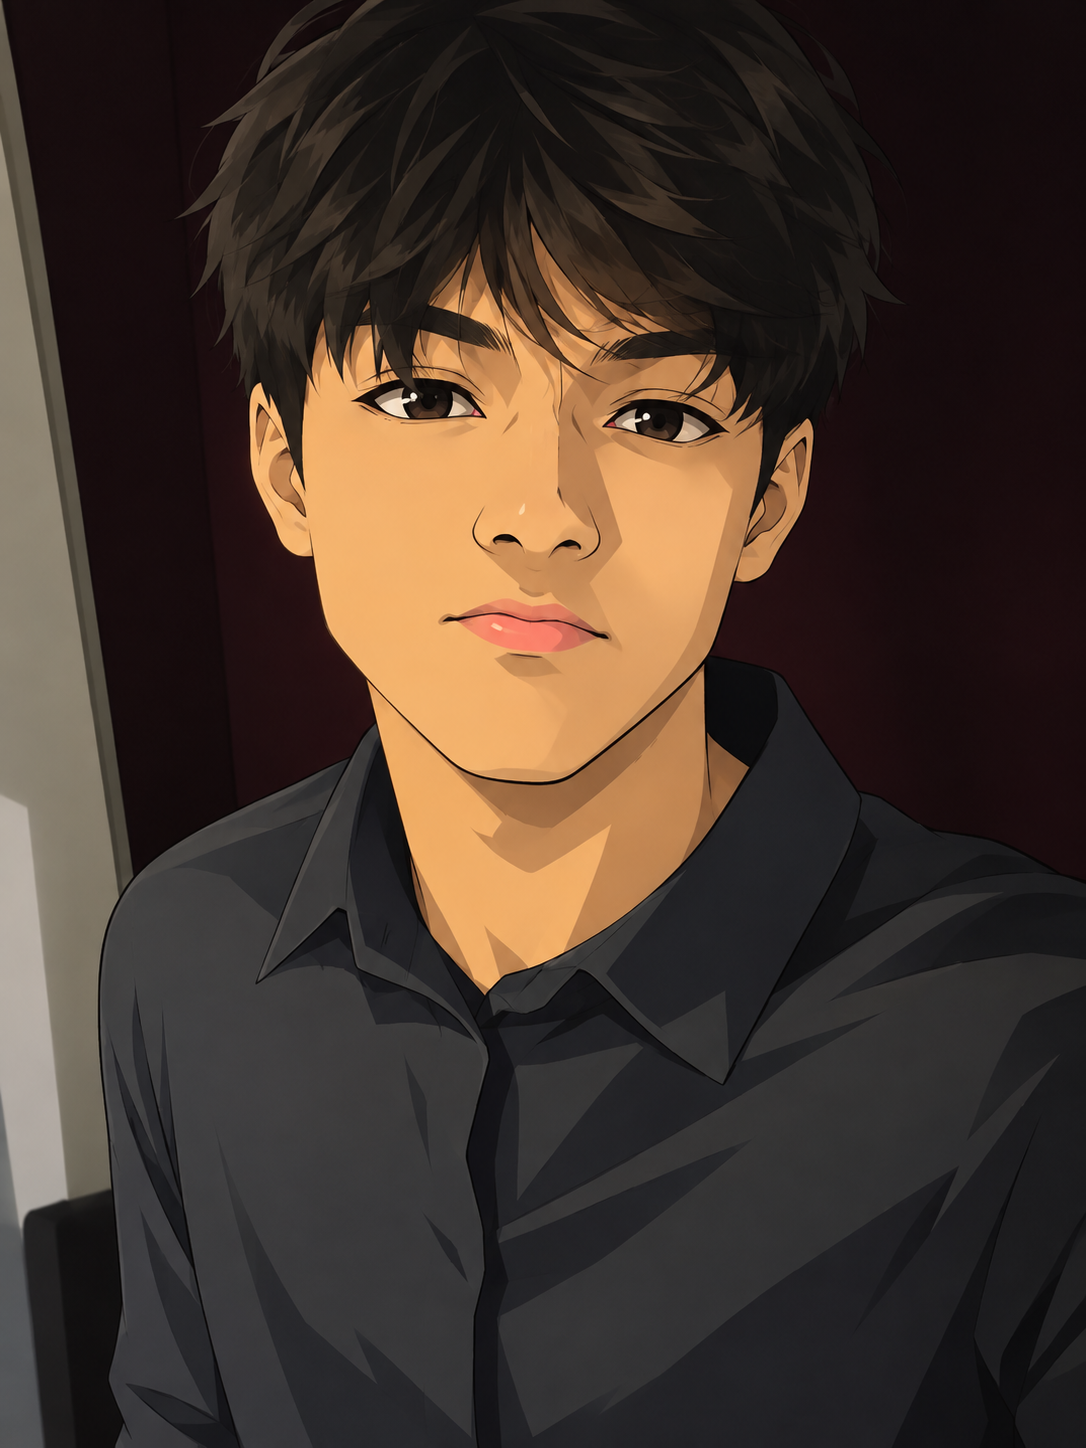

Nombre del alumno: Diego Perez Garcia

Número de control: 23212635

Correo institucional: l23212635**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('Sistema2')
parameters.StopTime = '15';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';
x = sim('Sistema2',parameters);
t_data = (0:0.1:15)';
t= (0:0.001:15)';
Pa = interp1(t_data,x.Pa, t, 'previous');
writematrix(Pa,'signal.xlsx');


## Respuesta a los lazos abiertos

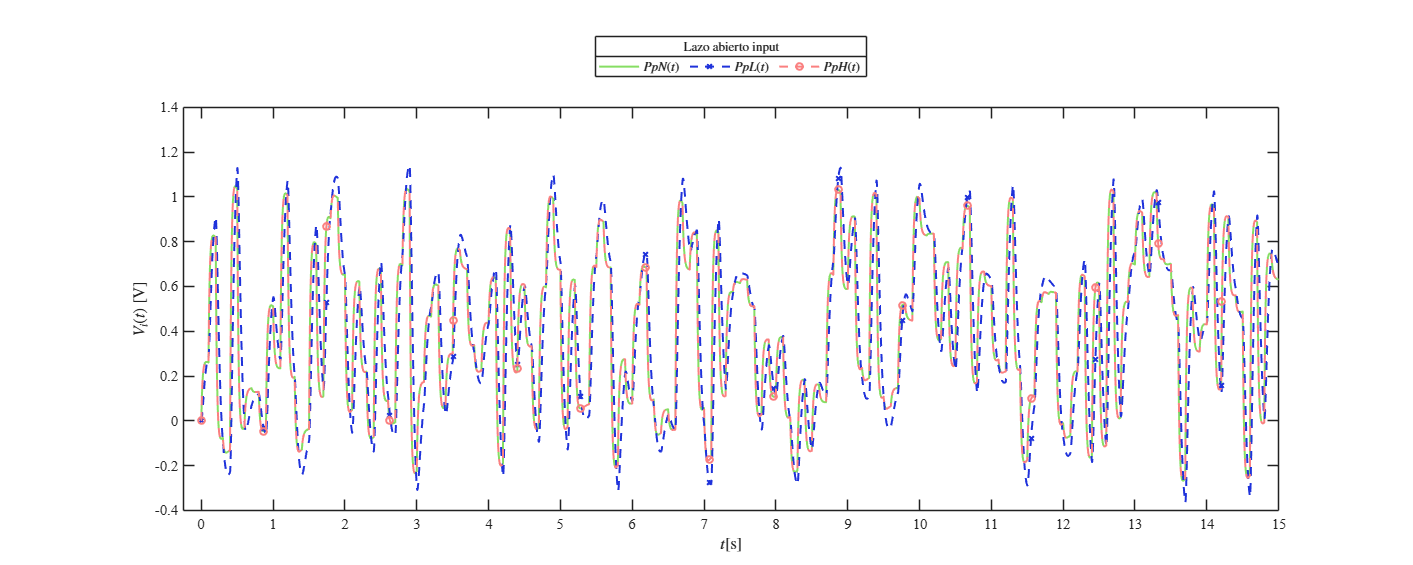


plotsignals(x.t,x.PpN,x.PpL,x.PpH,x.PIDH,x.PIDL,'Lazo abierto')

## Respuesta al hipotenso

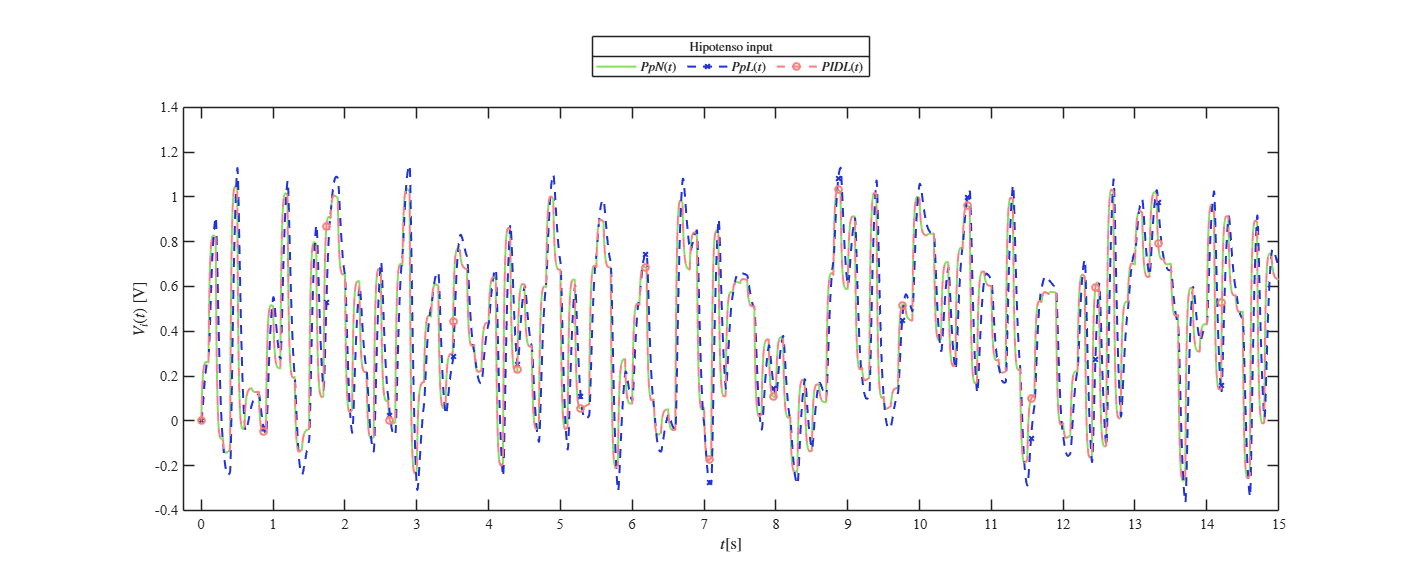


plotsignals(x.t,x.PpN,x.PpL,x.PpH,x.PIDH,x.PIDL,'Hipotenso')

## Respuesta del Hipertenso

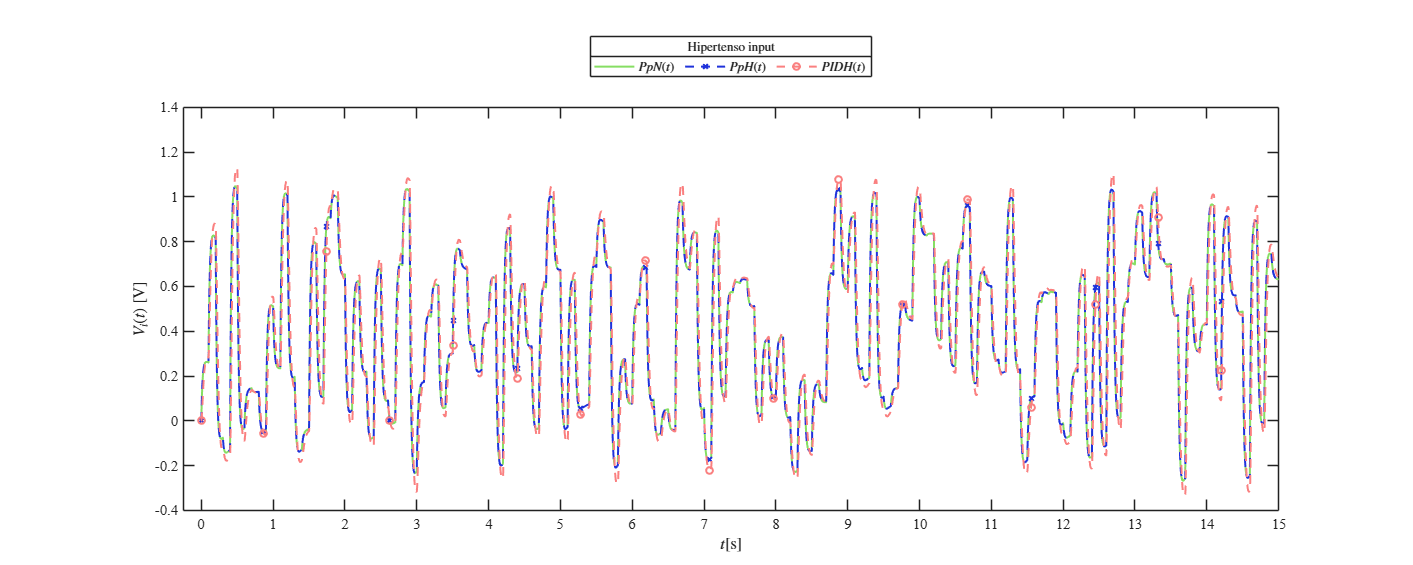


plotsignals(x.t,x.PpN,x.PpL,x.PpH,x.PIDH,x.PIDL,'Hipertenso')

## Funcion: Respuestas de la simulacion

function plotsignals (t,PpN,PpL,PpH,PIDL,PIDH,signal)
set(figure(),'color','w')
set(gcf,'units','inches','position',[1,1,25,10])
set(gca,'fontname','times new roman','fontsize',11)
hold on; grid off; box on;
clr1 = [118, 196, 87]/225;
clr2 = [27, 44, 193]/225;
clr3 = [221, 113, 113]/225;
order = [clr1;clr2;clr3]; colororder(order)
if signal == "Lazo abierto"
    plot(t,PpN,'-',t,PpL,'--x',t,PpH,'--o','LineWidth',1.5,'MarkerSize',5,'MarkerIndices',...
        1:1e3:length(t));
    L = legend('$PpN(t)$','$PpL(t)$','$PpH(t)$');
    
elseif signal == "Hipotenso"
    plot(t,PpN,'-',t,PpL,'--x',t,PIDL,'--o','LineWidth',1.5,'MarkerSize',5,'MarkerIndices',...
        1:1e3:length(t));
    L = legend('$PpN(t)$','$PpL(t)$','$PIDL(t)$');
    
elseif signal == "Hipertenso"
    plot(t,PpN,'-',t,PpH,'--x',t,PIDH,'--o','LineWidth',1.5,'MarkerSize',5,'MarkerIndices',...
        1:1e3:length(t));
    L = legend('$PpN(t)$','$PpH(t)$','$PIDH(t)$');
   
end
set(L,'interpreter','latex','location','northoutside','orientation','horizontal')
title(L,[signal,' input'])
xlabel('$t$[s]','interpreter','latex')
ylabel('$V_i(t)$ [V]','interpreter','latex')
xlim([-0.25 15]); xticks(0:1:15)
ylim([-0.4 1.4]); yticks(-0.4:0.2:1.4)
exportgraphics(gcf,[signal,'_matlab1.pdf'],'contenttype','vector')
end
